### This is a MATLAB live script for analyzing the first guesses of reponses to Guess the Number game

small interval: [1    10], n = 6

mid interval: [1    1,000], n = 30

big interval: [1    100,000], n = 4

% This is the data for the first guess of participants who played the
% mid-sized interval ([1, 1000]) version of the "Guess the Number" game
data = [590, 500, 500, 800, 500, 69, 500, 22, 500, 56, 500, 100, 500, 200, 500, ...
    500, 500, 877, 700, 45, 500, 234, 239, 921, 500, 500, 500, 500, 529, 764]';
% create a logical vector of whether person knows bisection search
class = logical([1, 1, 1, 0, 1, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1, 1, 1, ...
    0, 0, 1, 0, 0, 0, 0, 0, 0, 1, 1, 0, 1]); % 1 if participant knew Bisection Search
n = length(data)

n = 30

disp(["mean of first guess", num2str(mean(data))])

    "mean of first guess"    "454.8667"



disp(["standard deviation of first guess", num2str(std(data))])

    "standard deviation of first guess"    "240.2714"



% Perform Kolomogorov-Lilliefors to test if the data is Gaussian distributed
h = lillietest(data);
if h == 1
    disp("Kolmogorov-Lilliefors: The data is NOT Gaussian")
else
    disp("Kolmogorov-Lilliefors: The data my be Gaussian")
end

Kolmogorov-Lilliefors: The data is NOT Gaussian


#### Analyzing the data for people who know and don't know Binary Search together

hist = histogram(data, 9);
hold on
binEdges = hist.BinEdges;
binCenters = binEdges(1:end-1) + diff(binEdges)/2;
obsCounts = hist.BinCounts % frequency 

obsCounts =      5     1     2     0    16     1     2     2     1


% Create a vector containing the observed counts for each bin and compute the total number of observations.
pd = makedist('Normal', 'mu', 500, 'sigma', std(data)); % estimate standard deviation from the data
expCounts = round(n * diff(cdf(pd, binEdges))) % expected counts using truncated Normal distribution

expCounts =      1     2     4     5     5     5     4     2     1


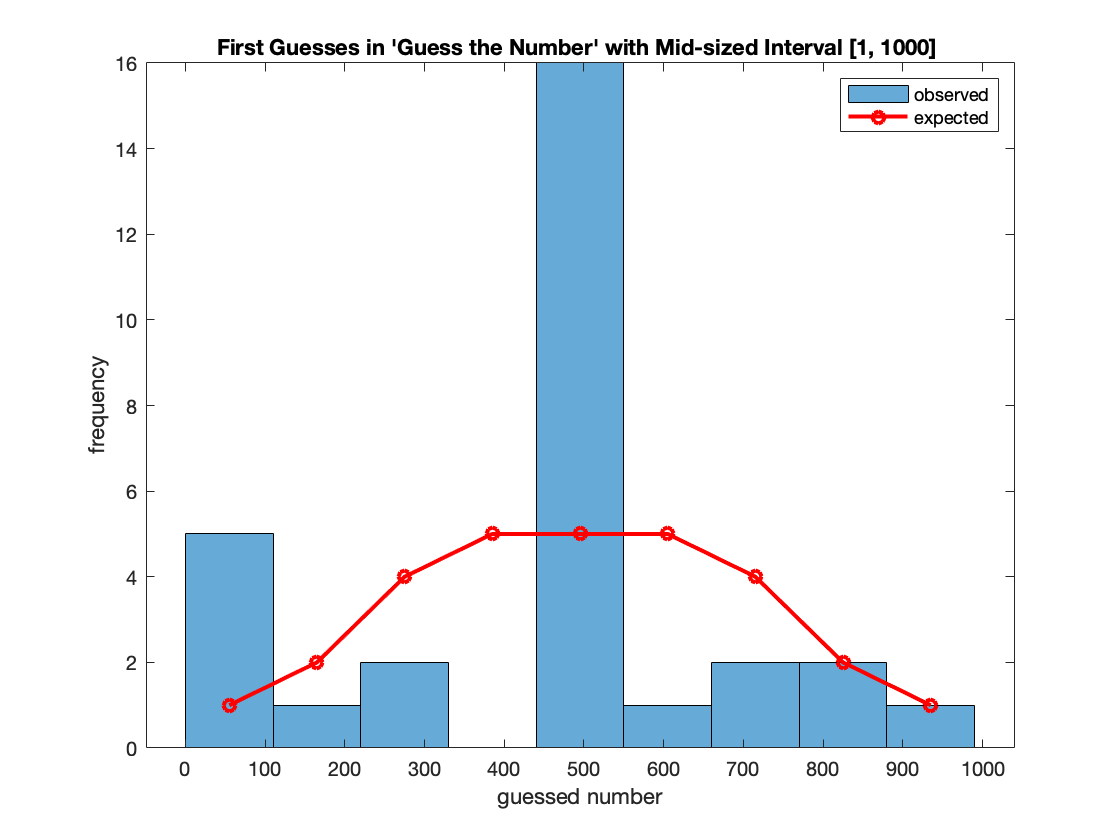

plot(binCenters, expCounts,'LineWidth',2, 'Color', 'r', "Marker", "o")
xlabel("guessed number"); ylabel("frequency"); 
title("First Guesses in 'Guess the Number' with Mid-sized Interval [1, 1000] ")
legend("observed", "expected")
hold off


% Perform Chi-Squared to test if the data is Gaussian with mean 500
% [h,p,st] = chi2gof(data, 'Edges', binEdges, 'CDF', pd, 'NParams', 1) 
[h,p,st] = chi2gof(data, 'CDF', pd, 'NParams', 1) % run when more data

h = 1

p = 0.0406

st = struct with fields:
    chi2stat: 4.1944
          df: 1
       edges: [22.0000 471.5000 921.0000]
           O: [8 22]
           E: [13.5837 16.4163]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 500")
end

Chi-squared: The first guess is NOT Gaussian with mean 500


#### Now split the data into those who knew Binary/Bisection Search and those who didn't

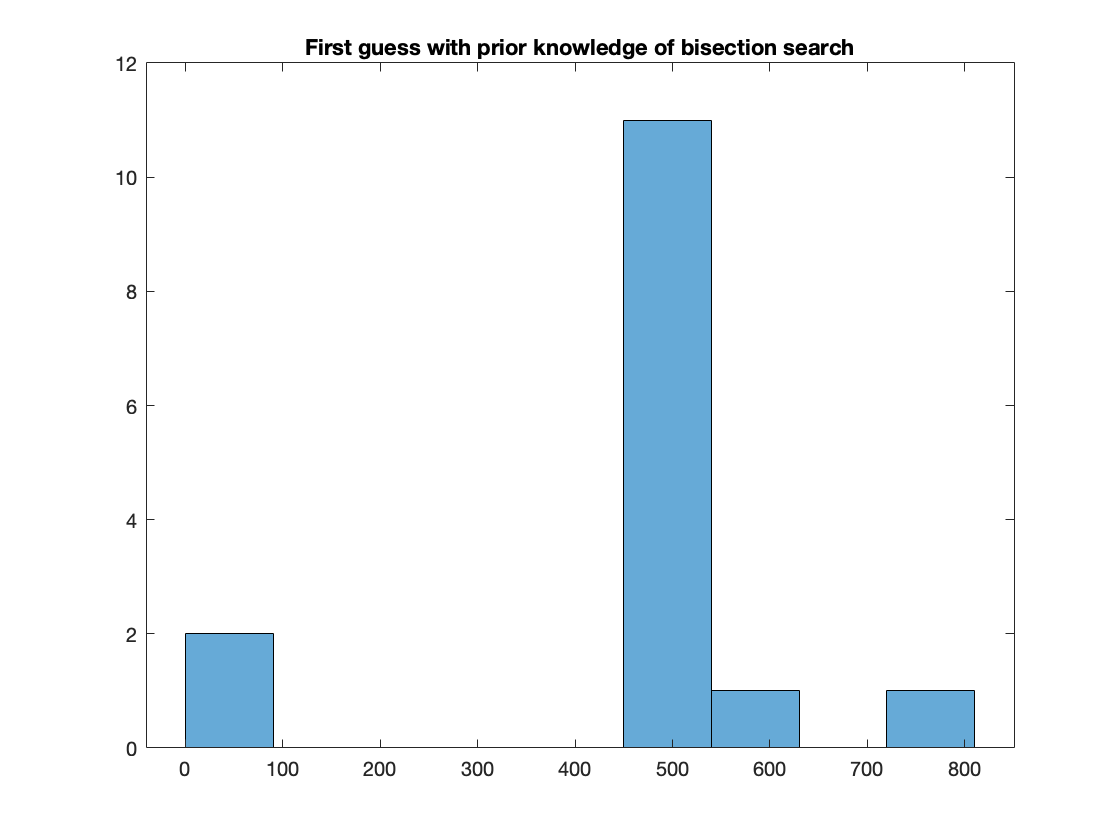

% People who knew bisection search
hist = histogram(data(class), 9);
title('First guess with prior knowledge of bisection search')

binEdges = hist.BinEdges;
binCenters = binEdges(1:end-1) + diff(binEdges)/2;
obsCounts = hist.BinCounts % frequency 

obsCounts =      2     0     0     0     0    11     1     0     1


% expCounts = round(n * diff(cdf(pd, binEdges))) % expected counts using Uniform distribution
% [h,p,st] = chi2gof(data, 'Edges', binEdges, 'CDF', pd, 'NParams', 1) 
[h,p,st] = chi2gof(data, 'CDF', pd, 'NParams', 1) % run when more data

h = 1

p = 0.0406

st = struct with fields:
    chi2stat: 4.1944
          df: 1
       edges: [22.0000 471.5000 921.0000]
           O: [8 22]
           E: [13.5837 16.4163]


if h == 1
    disp("Chi-squared: The first guess is NOT Gaussian with mean 500")
else
    disp("Chi-squared: The first guess may be Gaussian with mean 500")
end

Chi-squared: The first guess is NOT Gaussian with mean 500


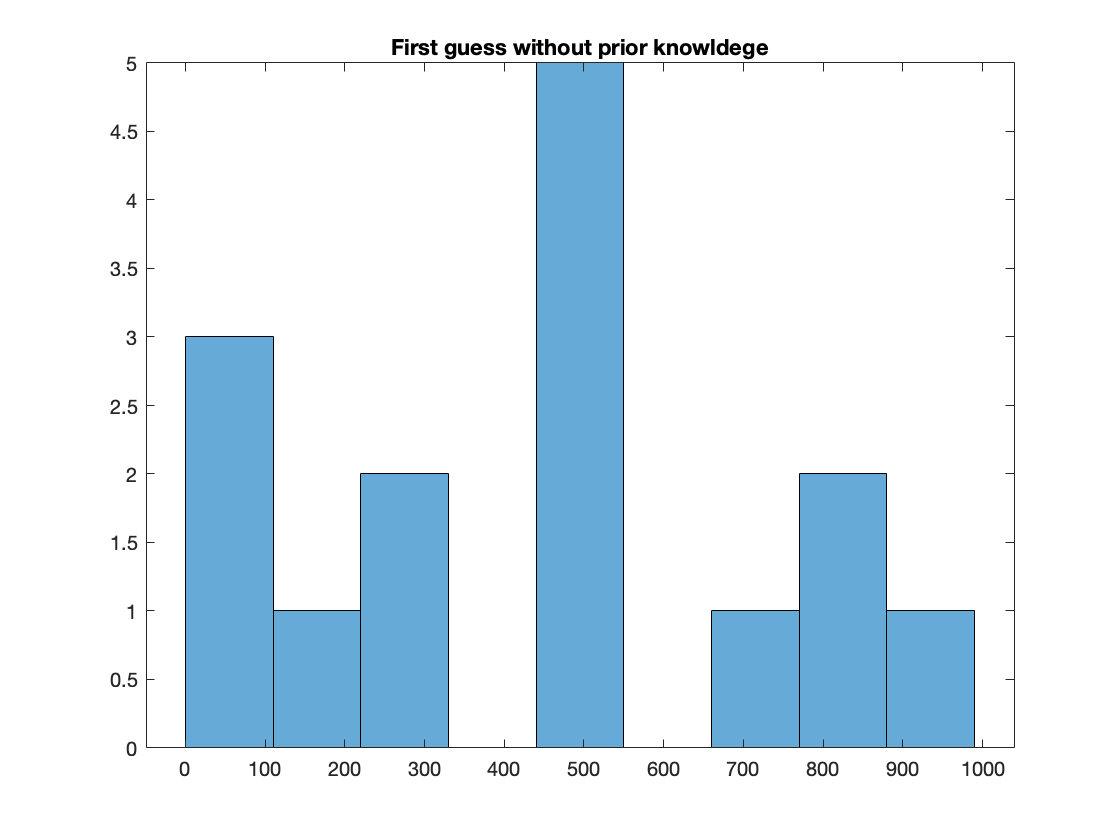


% People who did not know bisection search
hist = histogram(data(~class), 9);
title('First guess without prior knowldege')

pd = makedist('Uniform', "lower", 1, "upper", 1000); % Unif(a=1, b=1000)
binEdges = hist.BinEdges;
binCenters = binEdges(1:end-1) + diff(binEdges)/2;
obsCounts = hist.BinCounts

obsCounts =      3     1     2     0     5     0     1     2     1


% [h,p,st] = chi2gof(data(class), 'Edges', binEdges, 'CDF', pd, 'NParams', 0);  % perform Chi-squared test against Unif(a=1, b=1000)
[h,p,st] = chi2gof(data(class), 'CDF', pd, 'NParams', 0) % run when more data

h = 1

p = 0.0079

st = struct with fields:
    chi2stat: 7.0566
          df: 1
       edges: [45.0000 476.4000 764.0000]
           O: [2 13]
           E: [7.1381 7.8619]


if h == 1
    disp("Chi-squared: The first guess is NOT Uniform on [1, 1000]")
else
    disp("Chi-squared: The first guess may be Uniform on [1, 1000]")
end

Chi-squared: The first guess is NOT Uniform on [1, 1000]



% now we write the algorithm for true bisection search